## 一阶系统

clear

k_dc = 5;
Tc = 10;
u = 2;

s = tf('s');
G0 = k_dc/(Tc*s+1)

step(u*G0)

linearSystemAnalyzer('step',G0)

## 二阶系统

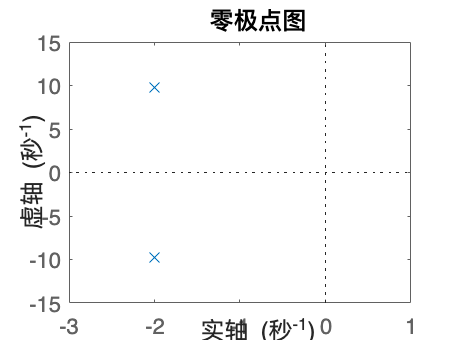

clear
close


k_dc = 1;
w_n = 10;
zeta1 = 0.2; % 欠阻尼系统
zeta2 = 1.5; % 过阻尼系统
zeta3 = 1;   % 临界阻尼系统
zeta4 = 0;   % 无阻尼系统

s = tf('s');
G1 = k_dc*w_n^2/(s^2+2*zeta1*w_n*s+w_n^2);
G2 = k_dc*w_n^2/(s^2+2*zeta2*w_n*s+w_n^2);
G3 = k_dc*w_n^2/(s^2+2*zeta3*w_n*s+w_n^2);
G4 = k_dc*w_n^2/(s^2+2*zeta4*w_n*s+w_n^2);

pzmap(G1)
axis([-3 1 -15 15])

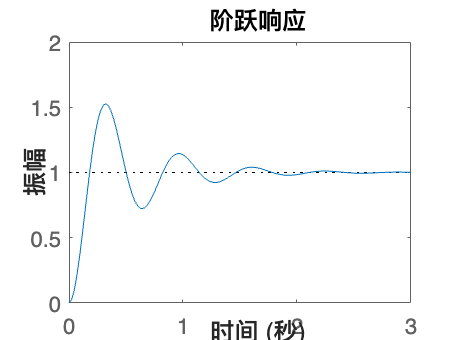

step(G1)
axis([0 3 0 2])

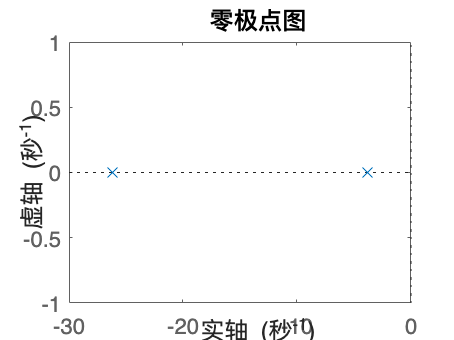


pzmap(G2)
axis([-30 0 -1 1])

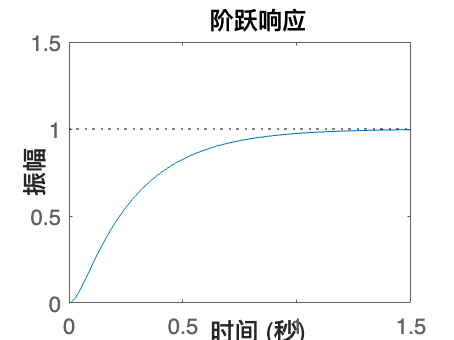

step(G2)
axis([0 1.5 0 1.5])

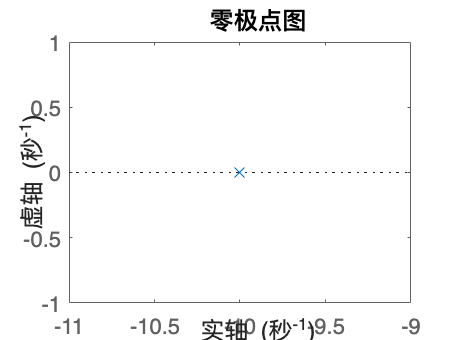


pzmap(G3)
axis([-11 -9 -1 1])

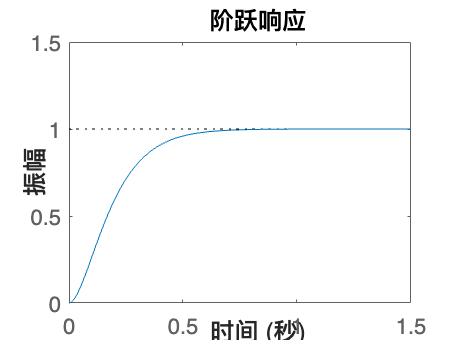

step(G3)
axis([0 1.5 0 1.5])

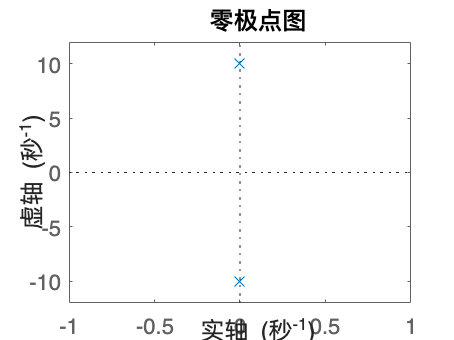


pzmap(G4)
axis([-1 1 -12 12])

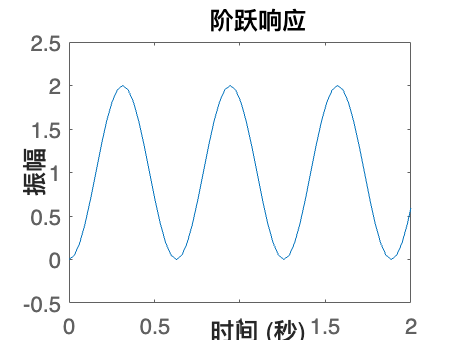

step(G4)
axis([0 2 -0.5 2.5])

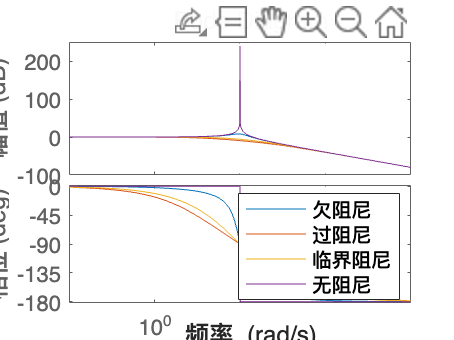


bode(G1,G2,G3,G4)
legend('欠阻尼','过阻尼','临界阻尼','无阻尼')